% Test Zone

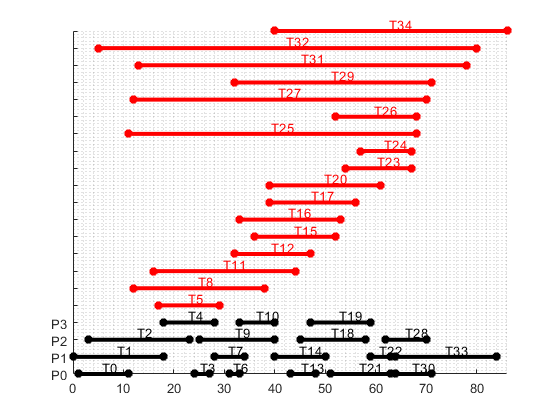

% Tabela de tasks

clear all
str = convertStringsToChars(splitlines(extractFileText('casks_35_04_1.txt')));
profits = str2double(splitlines(extractFileText('profits_35_04_1.txt')));
progs={};
prog={};
tasks={};
for p=1:(length(str)-1)
    if(str{p}(1)=='P')
        progs{p} = split(str(p));
        final = p;
    else
        tasks{(p-(final))}=split(str(p));
    end
end
margem = p*2/100;

figure(1)

%prints
close all
hold on
for  i= 1:final
    for k=3:3:(length(progs{i})-1)
        t=(str2double(progs{i}{k-1}):str2double(progs{i}{k+1}));
        p=ones(1,length(t));
        title = progs{i}{k};
        fim = length(regexp(title,'[0-9]'))+1;
        if fim ==2
            iprofit = str2num(title(2))+1;
        else
            iprofit = str2num(title(2:fim))+1;
        end
        if(profits(iprofit)~=1)
            txt = [progs{i}{k},' (',int2str(profits(iprofit)),')'];
            avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
        else
            txt = title;
            avg =(t(1)+(t(end)-t(1))/2)-0.3;
        end
        text(avg,i+margem,txt,'Color','k');
        prog{i} = char(progs{i}(1));
        plot(t, i*p, 'k-',"LineWidth",3);
        plot(t(1),i*p, 'k*',"LineWidth",3);
        plot(t(end),i*p, 'k*',"LineWidth",3)
    end   
end

for q=1:length(tasks)
    t=(str2double(tasks{q}{1}):str2double(tasks{q}{3}));
    p=ones(1,length(t));
    title = tasks{q}{2};
    fim = length(regexp(title,'[0-9]'))+1;
    iprofit = str2num(title(2:fim))+1;
    if(profits(iprofit)~=1)
        txt = [tasks{q}{2},' (',int2str(profits(iprofit)),')'];
        avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
    else
        txt = title;
        avg =(t(1)+(t(end)-t(1))/2)-0.3;
    end
    text(avg,((q+final)+margem),txt,'Color','r');
    plot(t, (q+final)*p, 'r-',"LineWidth",3);
    plot(t(1),(q+final)*p, 'r*',"LineWidth",3);
    plot(t(end),(q+final)*p, 'r*',"LineWidth",3)
    prog{q+final} = char('');
end
hold off
grid("minor");
ay = gca;
ay.YTickLabel = prog;
yticks(1:length(prog));
axis(ay,"tight");

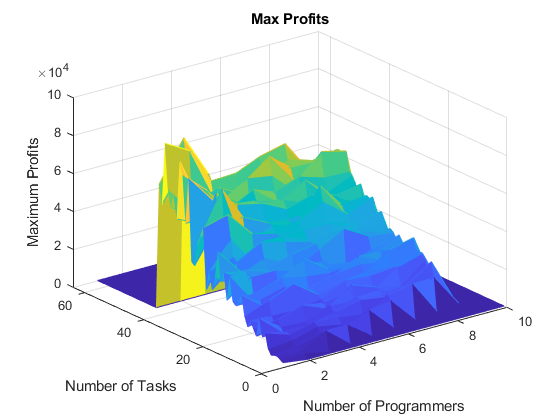

% Results profits

clear all
results = load('./c results/files098475/profits0.txt');
tasks=results(:,1);
progs=results(:,2);
profit=results(:,3);
profits= zeros(64,10);
for i=1:length(profit)
        profits(tasks(i),progs(i))=profit(i);
end
m = mesh(profits);
%m.FaceColor = 'flat';
title("Max Profits")
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Maximum Profits");

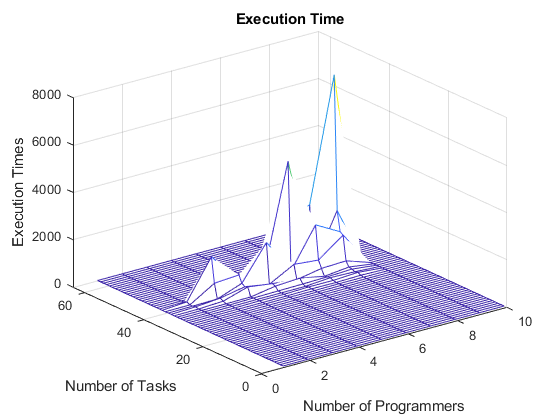

% Results time

clear all
results = load('./c results/files098475/Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=time(i);
end
m = mesh(times);
%m.FaceColor = 'flat';
title("Execution Time")
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Execution Times");

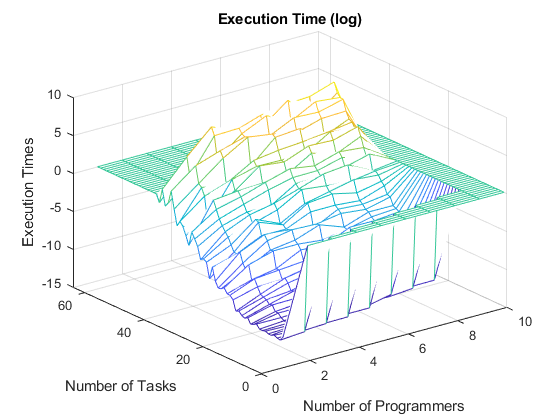

% Results time (log)

clear all
results = load('./c results/files098475/Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=log(time(i));
end
mesh(times);
title("Execution Time (log)")
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Execution Times");

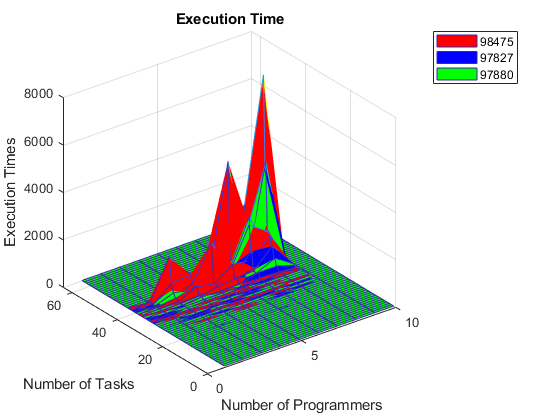

% Results time (all nmecs)

clear all

results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=time0(i);
end

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=time1(i);
end

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=time2(i);
end

r= mesh(times0);
r.FaceColor = 'r';
hold on;

m= mesh(times1);
m.FaceColor = 'b';

c= mesh(times2);
c.FaceColor = 'g';

hold off;
legend('98475','97827','97880')
title("Execution Time")
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Execution Times");

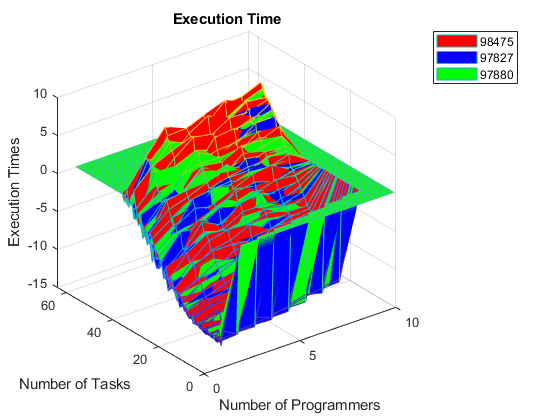

% Results time (all nmecs log)

clear all

results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=log(time0(i));
end

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=log(time1(i));
end

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=log(time2(i));
end

r= mesh(times0);
r.FaceColor = 'r';
hold on;

m= mesh(times1);
m.FaceColor = 'b';

c= mesh(times2);
c.FaceColor = 'g';

hold off;
legend('98475','97827','97880');
title("Execution Time");
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Execution Times");

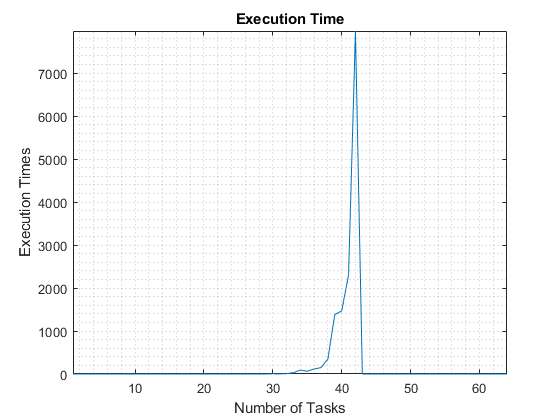

% Results time 2d (muda o numero de tasks)

clear all
prog=8;                                     % numero fixo de progs, mudar para o pretendido
results = load('./c results/files098475/Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=time(i);
end
result=times(:,prog);
plot(result);

grid("minor");
title("Execution Time")
xlabel("Number of Tasks");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

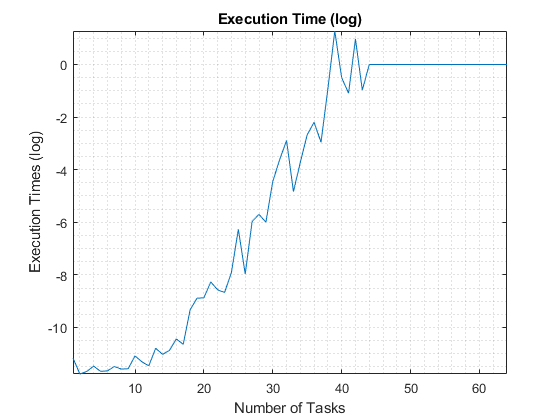

% Results time 2d (log) (muda o numero de tasks)

clear all
prog=1;                                     % numero fixo de progs, mudar para o pretendido
results = load('c results\files098475\Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=log(time(i));
end
result=times(:,prog);
plot(result);
grid("minor");
title("Execution Time (log)")
xlabel("Number of Tasks");
ylabel("Execution Times (log)");
ax=gca;
axis(ax,"tight");

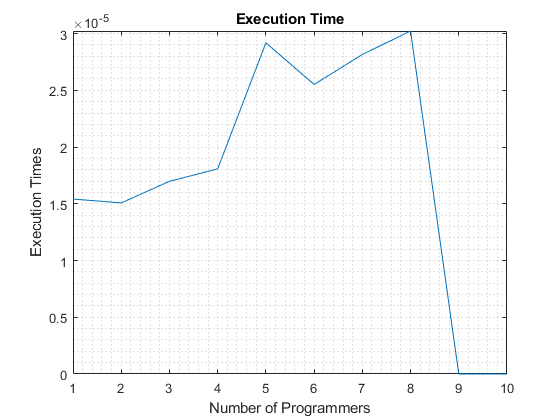

% Results time 2d (muda o numero de progs)

clear all
task=10;                                     % numero fixo de tasks, mudar para o pretendido
results = load('c results\files098475\Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=time(i);
end
result=times(task,:);
plot(result);
grid("minor");
title("Execution Time")
xlabel("Number of Programmers");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

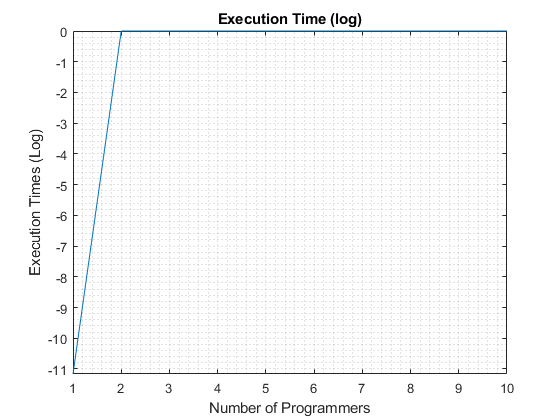

% Results time 2d (log) (muda o numero de progs)

clear all
task=1;                                     % numero fixo de tasks, mudar para o pretendido
results = load('c results\files098475\Execution_Times0.txt');
tasks=results(:,1);
progs=results(:,2);
time=results(:,3);
times= zeros(64,10);
for i=1:length(time)
        times(tasks(i),progs(i))=log(time(i));
end
result=times(task,:);
plot(result);
grid("minor");
title("Execution Time (log)")
xlabel("Number of Programmers");
ylabel("Execution Times (Log)");
ax=gca;
axis(ax,"tight");

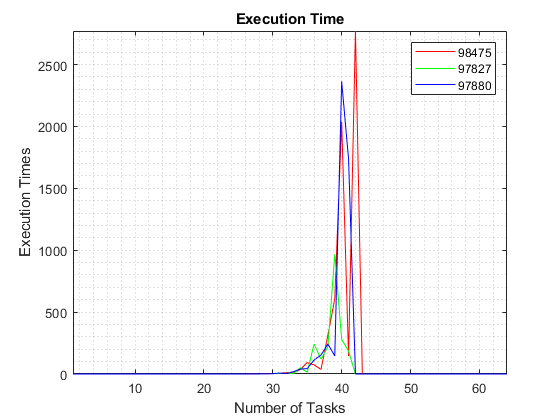

% Results time all nmecs 2d (muda o numero de tasks)

clear all
prog=7;                                     % numero fixo de progs, mudar para o pretendido

results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=time0(i);
end
result0=times0(:,prog);

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=time1(i);
end
result1=times1(:,prog);

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=time2(i);
end
result2=times2(:,prog);

plot(result0,'r');
hold on;
plot(result1,'g');
plot(result2,'b');
hold off;

legend('98475','97827','97880');
grid("minor");
title("Execution Time")
xlabel("Number of Tasks");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

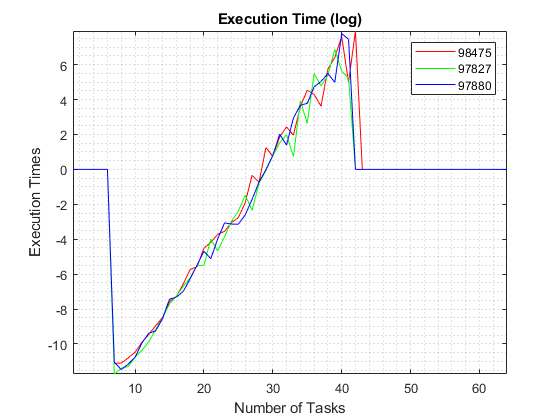

% Results time all nmecs 2d (log) (muda o numero de tasks)

clear all
prog=7;                                     % numero fixo de progs, mudar para o pretendido

results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=log(time0(i));
end
result0=times0(:,prog);

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=log(time1(i));
end
result1=times1(:,prog);

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=log(time2(i));
end
result2=times2(:,prog);

plot(result0,'r');
hold on;
plot(result1,'g');
plot(result2,'b');
hold off;

legend('98475','97827','97880');
grid("minor");
title("Execution Time (log)")
xlabel("Number of Tasks");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

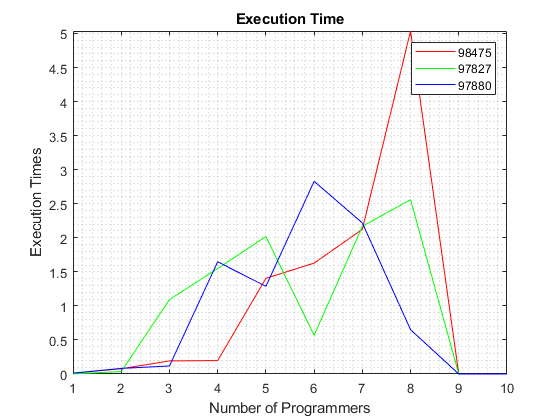

% Results time all nmecs 2d (muda o numero de progs)

clear all
task=30;                                     % numero fixo de tasks, mudar para o pretendido


results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=time0(i);
end
result0=times0(task,:);

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=time1(i);
end
result1=times1(task,:);

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=time2(i);
end
result2=times2(task,:);

plot(result0,'r');
hold on;
plot(result1,'g');
plot(result2,'b');
hold off;

legend('98475','97827','97880');
grid("minor");
title("Execution Time")
xlabel("Number of Programmers");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

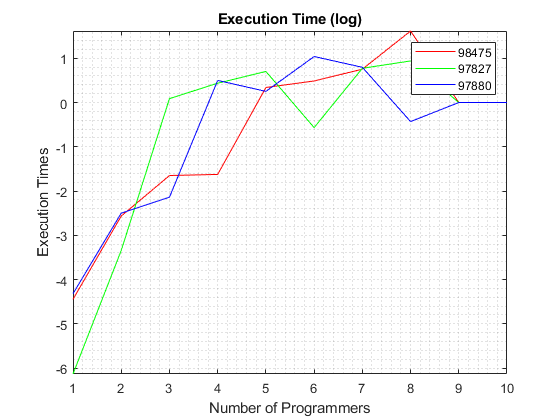

% Results time all nmecs 2d (log) (muda o numero de progs)

clear all
task=30;                                     % numero fixo de tasks, mudar para o pretendido


results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=log(time0(i));
end
result0=times0(task,:);

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=log(time1(i));
end
result1=times1(task,:);

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=log(time2(i));
end
result2=times2(task,:);

plot(result0,'r');
hold on;
plot(result1,'g');
plot(result2,'b');
hold off;

legend('98475','97827','97880');
grid("minor");
title("Execution Time (log)")
xlabel("Number of Programmers");
ylabel("Execution Times");
ax=gca;
axis(ax,"tight");

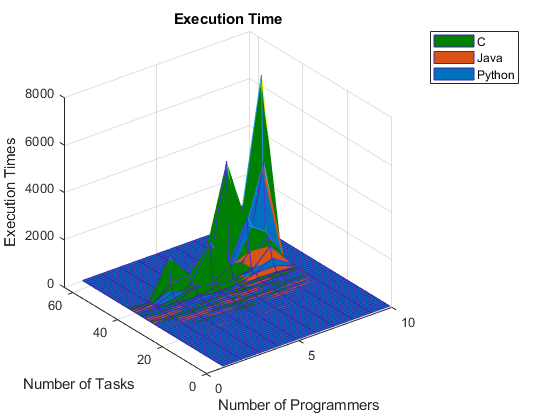

% Results time (all languages)

clear all

results0 = load('./c results/files098475/Execution_Times0.txt');
tasks0=results0(:,1);
progs0=results0(:,2);
time0=results0(:,3);
times0= zeros(64,10);
for i=1:length(time0)
        times0(tasks0(i),progs0(i))=time0(i);
end

results1 = load('./c results/files097827/Execution_Times0.txt');
tasks1=results1(:,1);
progs1=results1(:,2);
time1=results1(:,3);
times1= zeros(64,10);
for i=1:length(time1)
        times1(tasks1(i),progs1(i))=time1(i);
end

results2 = load('./c results/files097880/Execution_Times0.txt');
tasks2=results2(:,1);
progs2=results2(:,2);
time2=results2(:,3);
times2= zeros(64,10);
for i=1:length(time2)
        times2(tasks2(i),progs2(i))=time2(i);
end

r= mesh(times0);
r.FaceColor = [0, 0.5, 0];
hold on;

m= mesh(times1);
m.FaceColor = [0.8500, 0.3250, 0.0980];

c= mesh(times2);
c.FaceColor = [0, 0.4470, 0.7410];

hold off;
legend('C','Java','Python');
title("Execution Time");
ylabel("Number of Tasks");
xlabel("Number of Programmers");
zlabel("Execution Times");

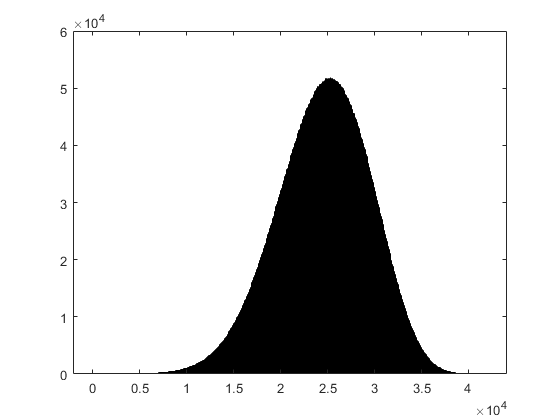

% Histograma

clear all

results = load('./c results/Histograma data/27_06_0.txt');
h=histogram(results);
h.FaceColor=[0.4940 0.1840 0.5560];